## Ann Fiegel - Class Project Part 3

Module 2, Project Bank Question 2

Battery Discharge Model

Objective: Simulate battery voltage or energy decay under constant and variable load conditions. 

Core Tasks:

Implement energy or change depletion logic

Compare different discharge rates

Key Deliverables: Voltage/energy vs time plots and discussion of battery performance. 

For this solution it is assumed that the input voltage is 9v

The fist section investigates constant resistance on the circuit.  

t = [0:1:100] % setting range values for the time over which the battery decay is being modeled

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


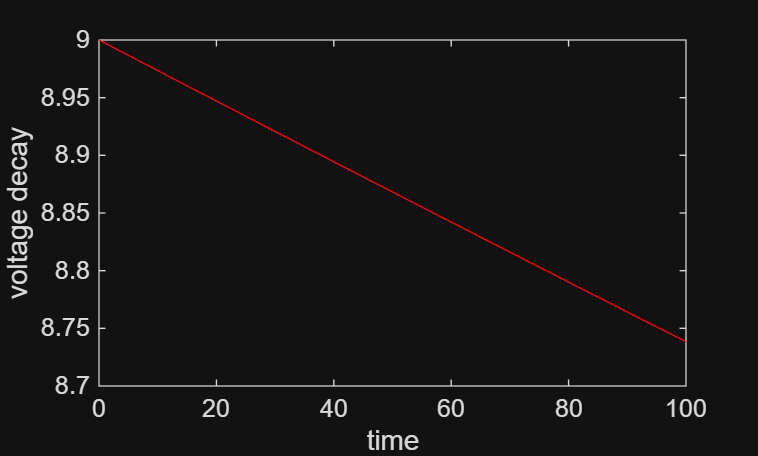


function D = f(lambda, t) %creating a function that models the decay of the battery over time

D = 9*exp(-1.*lambda.*t); % calculating values for the voltage decay at the various point of t

end % end of function 

function lambda = g(I) % creating a fucntion to calculate lambda that takes current in amps as an input as well as time

lambda = (log(10))./(320./I); % calculating lambda

end % end of function

lambda = g(0.041); % cacluating lambda with a 0.041A current

D = f(lambda, t); % calculating the decay of the battery


plot(t, D, 'r-'); % plotting voltage decay vs time
xlabel('time');
ylabel('voltage decay');

This next section examines what happens when the load is variable.

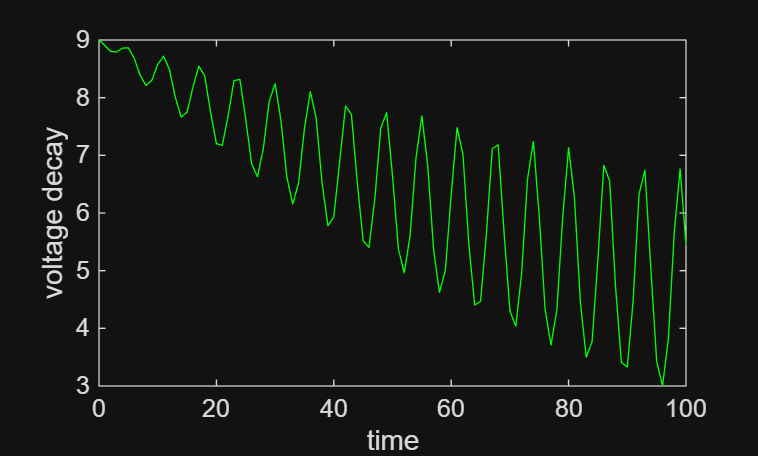

function I = h(t) % creating a function when resistance is variable causing the current to change with time

I = 0.6*sin(t) + 1; % the function chosen to model the varying current is a sinusoid

end % end of current function

I = h(t); % calculating varying current

lambda = g(I); % calculating new lambda

D = f(lambda, t); % calculating new voltage drop with time

plot(t, D, 'g-'); % plotting the voltage decay vs time with new D values
xlabel('time');
ylabel('voltage decay');

Both curves displayed for this problem show the voltage decay of a 9v battery. When the load is constant the decay of the battery is relatively constant. When the load is variable the decay is very different though, and ends at a much lower value. This shows that the battery preformes better under constant load. 